### Spatial and Temporal Plots for $\epsilon$

% Spacial variations

L = 1e-2;
N_L = 100;
mu_0 = pi*4e-7;
eps_0 = 8.85418782e-12;
omega = 2*pi*(10^(10));
Z_L = 1e2;
vp = 0.15e8;
z = linspace(0, L, N_L);

E = omega/vp;
%Gamma = 0.5*z.*exp(-E.*1j.*z);
%dGamma = 0.5*(-1j.*E)*z.*exp(-E.*1j.*z) + 0.5*exp(-E.*1j.*z);

Gamma = 0.5*exp(-E.*z);
dGamma = 0.5*(-E)*exp(-E.*z);

% Fourier transform of Gamma
f = linspace(0,omega/2,500);
H = fftshift(fft(Gamma, length(f)));
Hdb = 20*log10(abs(H)/max(abs(H))); % convert to dB

% find a and b
a = -2*dGamma.*(1./(1-Gamma.^2));
b = 4*1j*omega*sqrt(mu_0)*(Gamma./(1-Gamma.^2));

% Numerically integrate a from L to z
int_a = cumtrapz(a)*(L/N_L) - trapz(a)*(L/N_L);

% Calculate I(z)
I = exp(-int_a);
D = cumtrapz(I.*b)*(L/N_L) - trapz(I.*b)*(L/N_L);

% find eps(z)
epsz = ( I(N_L)*(Z_L/sqrt(mu_0))*I.^(-1) + I.^(-1).*D ).^(-2);

disp(epsz)

   1.0e-09 *

   0.1402 + 0.6925i   0.3239 + 0.2879i   0.2649 + 0.1164i   0.2118 + 0.0538i   0.1789 + 0.0278i   0.1590 + 0.0155i   0.1469 + 0.0092i   0.1393 + 0.0056i   0.1344 + 0.0035i   0.1314 + 0.0022i   0.1294 + 0.0014i   0.1281 + 0.0009i   0.1272 + 0.0006i   0.1267 + 0.0004i   0.1263 + 0.0003i   0.1261 + 0.0002i   0.1260 + 0.0001i   0.1259 + 0.0001i   0.1258 + 0.0000i   0.1257 + 0.0000i   0.1257 + 0.0000i   0.1257 + 0.0000i   0.1257 + 0.0000i   0.1257 + 0.0000i   0.1257 + 0.0000i   0.1257 + 0.0000i   0.1257 + 0.0000i   0.1257 + 0.0000i   0.1257 + 0.0000i   0.1257 + 0.0000i   0.1257 + 0.0000i   0.1257 + 0.0000i   0.1257 + 0.0000i   0.1257 + 0.0000i   0.1257 + 0.0000i   0.1257 + 0.0000i   0.1257 + 0.0000i   0.1257 + 0.0000i   0.1257 + 0.0000i   0.1257 + 0.0000i   0.1257 + 0.0000i   0.1257 + 0.0000i   0.1257 + 0.0000i   0.1257 + 0.0000i   0.1257 + 0.0000i   0.1257 + 0.0000i   0.1257 + 0.0000i   0.1257 + 0.0000i   0.1257 + 0.0000i   0.1257 + 0.0000i   0.1257 + 0.0000i   0.1257 + 0.000

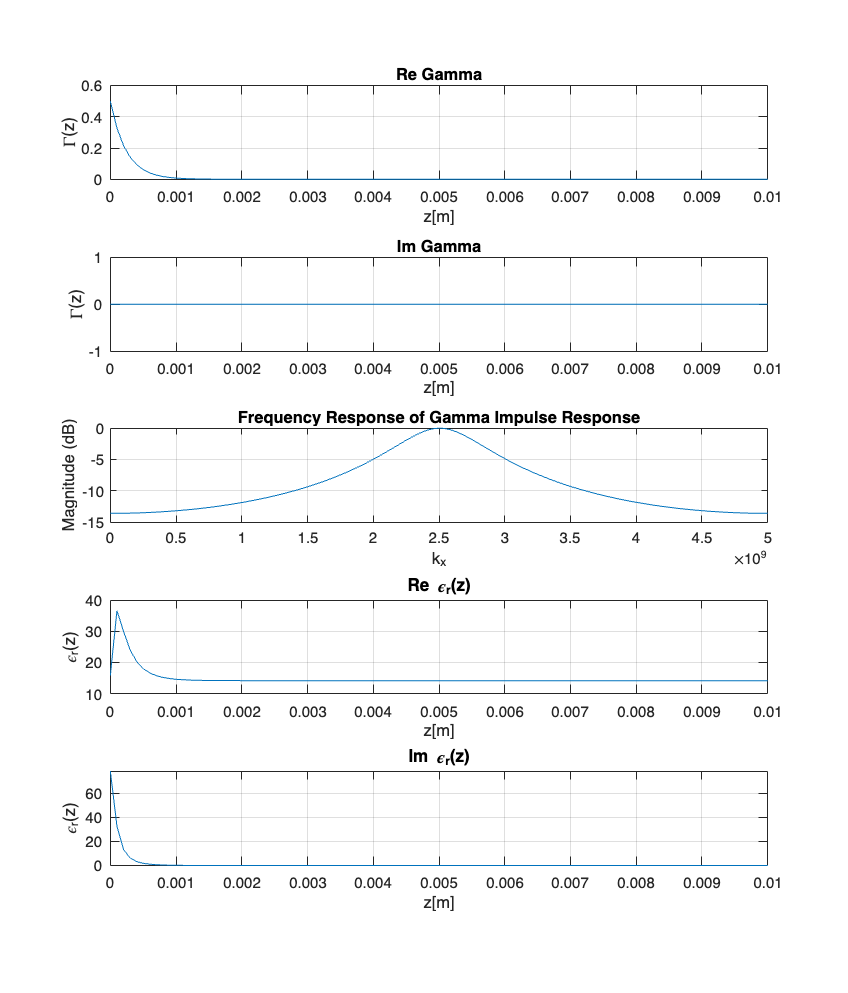


figure1=figure('Position', [100, 100, 1024, 1200]);
subplot(5,1,1)
plot(z, real(Gamma))
grid("on")
xlabel("z[m]")
ylabel("\Gamma(z)")
title("Re Gamma")

subplot(5,1,2)
plot(z, imag(Gamma))
grid("on")
xlabel("z[m]")
ylabel("\Gamma(z)")
title("Im Gamma")

subplot(5,1,3)
plot(f/2/pi,Hdb)
xlabel('k_x')
ylabel('Magnitude (dB)')
grid("on")
title('Frequency Response of Gamma Impulse Response')

subplot(5,1,4)
plot(z, real(epsz/(eps_0)))
grid("on")
xlabel("z[m]")
ylabel("\epsilon_r(z)")
title("Re \epsilon_r(z)")

subplot(5,1,5)
plot(z, imag(epsz/(eps_0)))
grid("on")
xlabel("z[m]")
ylabel("\epsilon_r(z)")
title("Im \epsilon_r(z)")

Temporal change

clear Gamma dGamma
T = 1e-9;
N_T = 100;
t = linspace(0, T, N_T);

F = omega;

%Gamma = 0.5-0.5*t.*exp(-F.*1j.*t);
%dGamma = -0.5*exp(-F.*1j.*t) - 0.5*(-F.*1j)*exp(-F.*1j.*t);

Gamma = 0.5 - 0.5*exp(-F.*t);
dGamma =  - 0.5*(-F)*exp(-F.*t);


a = -2*dGamma.*(1./(1-Gamma.^2));
b = 4*1j*omega*sqrt(mu_0)*(Gamma./(1-Gamma.^2));

% Numerically integrate a from L to z
int_a = cumtrapz(a)*(T/N_T) - cumtrapz(a(1))*(T/N_T);

% Calculate I(z)
I = exp(int_a);

D = cumtrapz(I.*b)*(T/N_T) - cumtrapz(I(1)*b(1))*(T/N_T);
epst = ( I(1)*(1/(5*sqrt(eps_0)))*I.^(-1) + I.^(-1).*D ).^(-2);

disp(epst)

   1.0e-09 *

   0.2214 + 0.0000i   0.0830 - 0.0000i   0.0476 - 0.0000i   0.0347 - 0.0000i   0.0291 - 0.0000i   0.0264 - 0.0000i   0.0250 - 0.0000i   0.0243 - 0.0000i   0.0240 - 0.0000i   0.0238 - 0.0000i   0.0237 - 0.0000i   0.0236 - 0.0000i   0.0236 - 0.0000i   0.0236 - 0.0000i   0.0236 - 0.0000i   0.0236 - 0.0000i   0.0236 - 0.0000i   0.0236 - 0.0000i   0.0236 - 0.0000i   0.0236 - 0.0000i   0.0236 - 0.0000i   0.0236 - 0.0000i   0.0236 - 0.0000i   0.0236 - 0.0000i   0.0236 - 0.0000i   0.0236 - 0.0000i   0.0236 - 0.0000i   0.0236 - 0.0000i   0.0236 - 0.0000i   0.0236 - 0.0000i   0.0236 - 0.0000i   0.0236 - 0.0000i   0.0236 - 0.0000i   0.0236 - 0.0000i   0.0236 - 0.0000i   0.0236 - 0.0000i   0.0236 - 0.0000i   0.0236 - 0.0000i   0.0236 - 0.0000i   0.0236 - 0.0000i   0.0236 - 0.0000i   0.0236 - 0.0000i   0.0236 - 0.0000i   0.0236 - 0.0000i   0.0236 - 0.0000i   0.0236 - 0.0000i   0.0236 - 0.0000i   0.0236 - 0.0000i   0.0236 - 0.0000i   0.0236 - 0.0000i   0.0236 - 0.0000i   0.0236 - 0.000

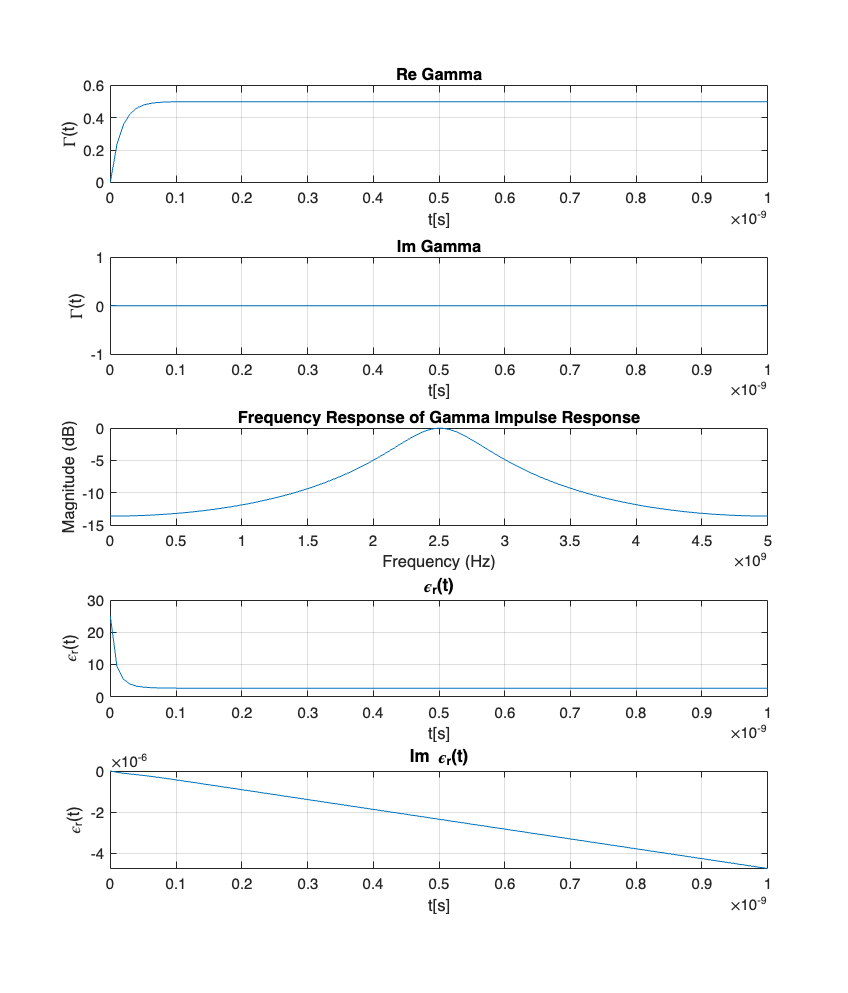


figure2=figure('Position', [100, 100, 1024, 1200]);
subplot(5,1,1)
plot(t, real(Gamma))
grid("on")
xlabel("t[s]")
ylabel("\Gamma(t)")
title("Re Gamma")

subplot(5,1,2)
plot(t, imag(Gamma))
grid("on")
xlabel("t[s]")
ylabel("\Gamma(t)")
title("Im Gamma")

subplot(5,1,3)
plot(f/2/pi,Hdb)
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
grid("on")
title('Frequency Response of Gamma Impulse Response')

subplot(5,1,4)
plot(t, abs(epst/(eps_0)))
grid("on")
xlabel("t[s]")
ylabel("\epsilon_r(t)")
title("\epsilon_r(t)")

subplot(5,1,5)
plot(t, imag(epst/(eps_0)))
grid("on")
xlabel("t[s]")
ylabel("\epsilon_r(t)")
title("Im \epsilon_r(t)")

### Relating with $L$ and $C$

Spatial profile